clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

'readgeoraster' requires Mapping Toolbox.

Error in ReadLayers (line 51)
    [Z,R] = readgeoraster(strcat(layerfolder, layers{1}),'CoordinateSystemType','geographic');

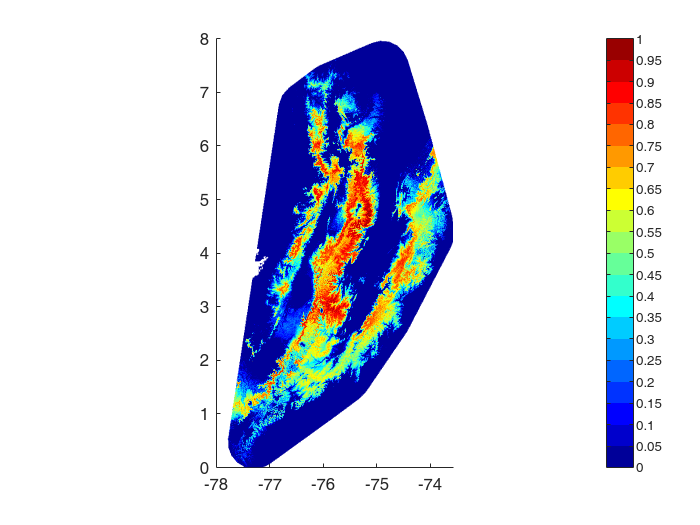

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

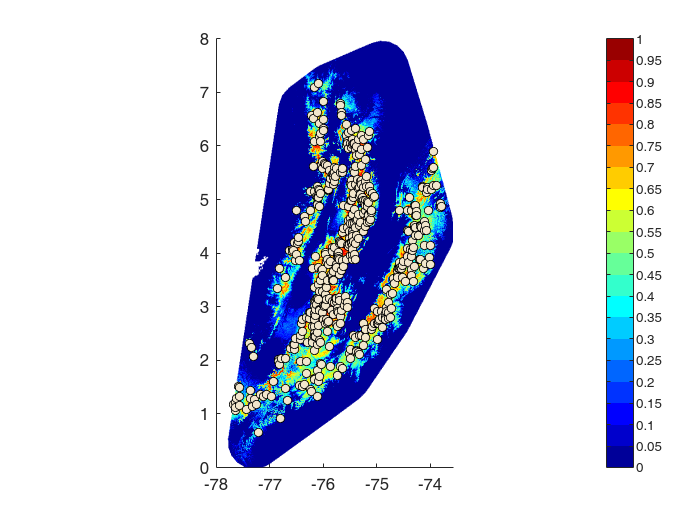

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, false, false);

----Finding correlation----
Elapsed time is 3.118692 seconds.
----Creating predictors----
¡All done!
Elapsed time is 3.224289 seconds.


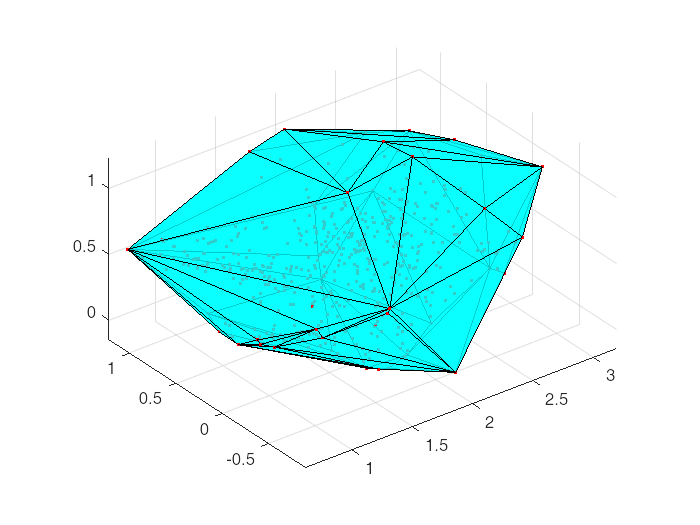

boundPointsIndex =     30
    32
    46
    47
    49
    60
    63
    86
   116
   118


boundPoints =     0.8370    0.8315    0.8407    0.6975    0.5596    0.8869    0.1143    0.6853    0.8210    0.4183    0.7588    0.8462    0.8889    0.2204    0.8250    0.8421    0.6667    0.8380    0.8378
    0.8967    0.9076    0.8901    0.2736    0.2798    0.2976    0.4571    0.2867    0.3100    0.1744    0.4033    0.9231    0.7778    0.6250    0.9000    0.9006    0.7647    0.8883    0.8919
    0.6304    0.6304    0.6264    0.5377    0.5052    0.3988    0.6000    0.6204    0.3819    0.1203    0.7505    1.0000    0.5556    0.3783    0.6900    0.6023    0.9412    0.6201    0.6324
    0.5815    0.5761    0.5824    0.5463    0.5207    0.4405    0.5714    0.6284    0.4022    0.5155    0.7588    0.9487    0.6667    0.2599    0.6300    0.5614    0.8431    0.5754    0.5838
    0.6793    0.6739    0.6758    0.8445    0.8109    1.0000    0.2571    0.8601    1.0000    0.6004    1.0000    0.5128    0.9444    0.3125    0.6500    0.7251    0.3725    0.6704    0.6757
    0.4620    0.4565    0.4670 

radius =     1.9263    1.9208    2.1615    2.1874    1.4237    2.0005    2.1439    1.7714    1.6198    1.5648    1.7470    1.6212    1.8752    1.9868    1.9643    1.7526    1.9420    2.0482    0.7975    1.4992    1.6686    1.3240    1.4023    1.5003    0.9786    1.4194    1.7912    1.1988    1.7618         0    1.5412    1.2436    1.8575    0.8150    0.6606    1.2006    1.2153    1.2002    1.6259    1.6124    1.6304    1.7745    1.1538    1.8588    1.7226    1.1480    1.0774    1.3603    0.8103    1.3458
    1.4123    1.3831    1.5852    1.8160    0.5405    1.8388    1.6283    1.4949    0.9789    0.9445    2.0214    1.1315    1.3275    2.2519    1.6134    1.9269    1.5458    1.5063    0.7320    0.9880    1.4884    0.8983    1.4425    1.5390    1.1372    1.5778    1.8863    0.1655    1.6280    1.2436    1.4472         0    1.8748    0.7325    0.9104    0.3349    1.4395    0.5356    1.5417    1.5587    1.4865    1.5403    0.8449    1.7964    1.5208    1.0139    1.1709    0.3686    1.8074

radiusClass =     0.7910    0.8155    0.6358    0.5216    0.3818    0.6875    0.6851    0.7989    0.7128    0.7925    0.8296    0.8188    0.8484    0.7744    0.5156    0.8512    0.5132    0.5020    0.6475    0.7626    0.4665    0.7475    0.7425    0.6951    0.2728    0.7153    0.5314    0.1655    0.6953         0    0.7520         0    0.4696    0.5706    0.6606    0.3349    0.4468    0.4126    0.6380    0.6383    0.6243    0.6386    0.6296    0.5274    0.5830         0         0    0.3686         0    0.6466


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
class = pcaO(data{1},show,outlier,outlier2);

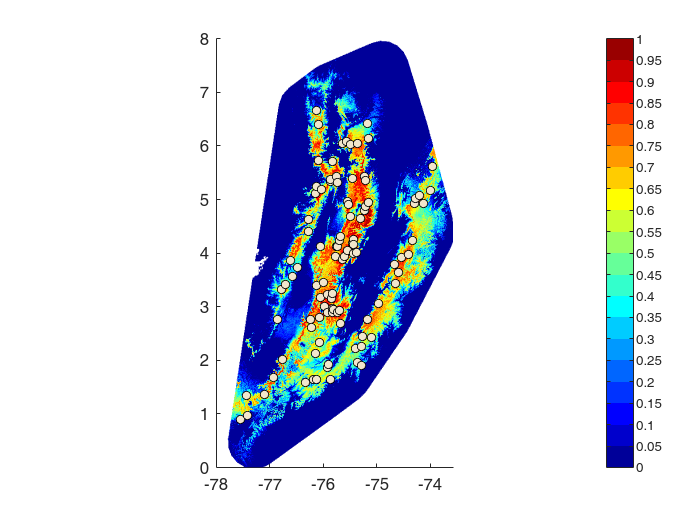

newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);

[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);

----Finding correlation----
Elapsed time is 2.086997 seconds.
----Creating predictors----
¡All done!
Elapsed time is 2.188308 seconds.


inBounds =    109    34    27    56    34     0     0    97    39   271   405   374   223    62    62   149   314    26   128     8    59   374   366    19   295   275   257   151   274   309   352    23   366   311   296   287    34   209   353   257    77   366   136   290   284     6   168   374    64   189


a =     0.2354    0.0734    0.0583    0.1210    0.0734         0         0    0.2095    0.0842    0.5853    0.8747    0.8078    0.4816    0.1339    0.1339    0.3218    0.6782    0.0562    0.2765    0.0173    0.1274    0.8078    0.7905    0.0410    0.6371    0.5940    0.5551    0.3261    0.5918    0.6674    0.7603    0.0497    0.7905    0.6717    0.6393    0.6199    0.0734    0.4514    0.7624    0.5551    0.1663    0.7905    0.2937    0.6263    0.6134    0.0130    0.3629    0.8078    0.1382    0.4082


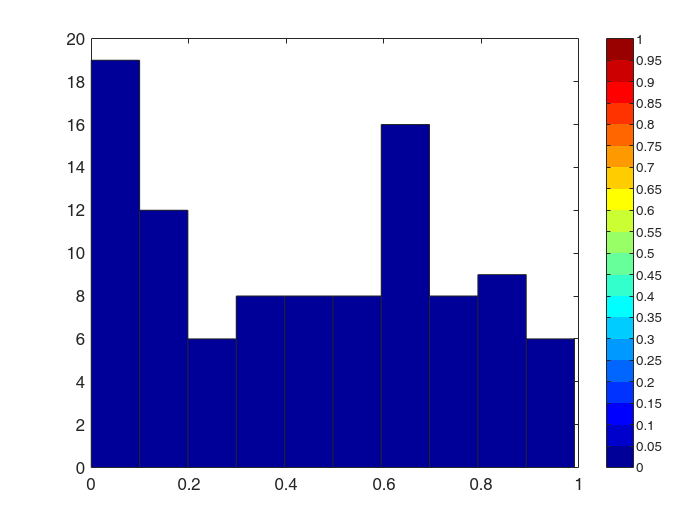

newPoints(dataNew{1},class)

dataf = bnm_modeling(data, '', true, 4, false);

----Modeling----


ij = 1

-Model 1


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)